`Erfan Panahi   810198369`

## Communication Systems I

# ***Computer Assignement 4*** 

## ***Contents:***

***    Part 1 . Probability and Statistics***

***    Part 2 . Random Processes***

***    Part 3 . Quantization***

#  ***Part 1.*** `Probability and Statistics`

`Plotting a 3d gaussian function:`

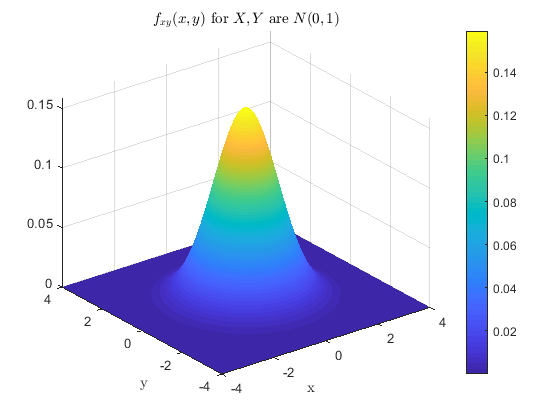

clear;
x0 = linspace(-4,4,500);
y0 = linspace(-4,4,500);
[X0,Y0] = meshgrid(x0,y0);
fxy = 1/(2*pi) * exp(-X0.^2/2 -Y0.^2/2);
surf(x0,y0,fxy);
shading interp;
colorbar;
title('$f_{xy}(x,y)$ for $X,Y$ are $N(0,1)$','interpreter','latex');
xlabel('x','interpreter','latex'); ylabel('y','interpreter','latex');

`Step1:`

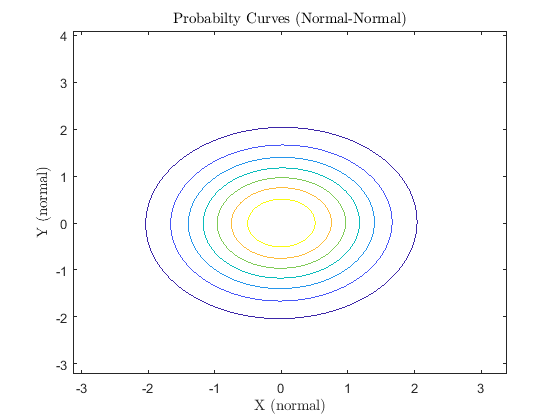

clear
L = 3000;
mu = 0;
sigma = 1;
X = normrnd(mu,sigma,[1,L]);
Y = normrnd(mu,sigma,[1,L]);
Part1_1(X,Y,mu,mu);
title('Probabilty Curves (Normal-Normal)','Interpreter','latex');
xlabel('X (normal)','Interpreter','latex');
ylabel('Y (normal)','Interpreter','latex');

`Step 2:`

`Normal - Uniform`

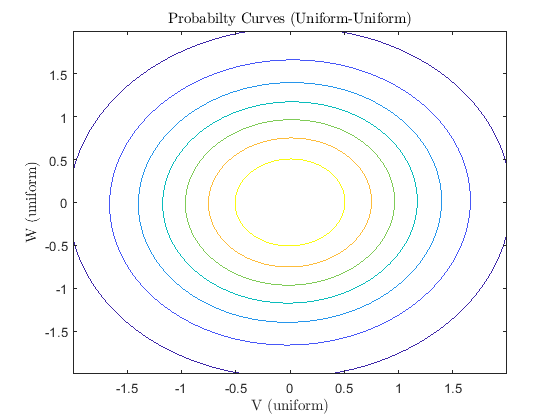

A = -2; B = 2;
V = unifrnd(A,B,[1,L]);
W = unifrnd(A,B,[1,L]);
Part1_1(V,W,(B+A)/2,(B+A)/2);
title('Probabilty Curves (Uniform-Uniform)','Interpreter','latex');
xlabel('V (uniform)','Interpreter','latex'); 
ylabel('W (uniform)','Interpreter','latex'); 

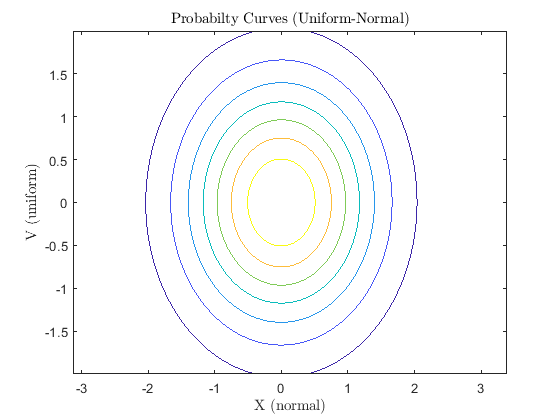

Part1_1(X,V,mu,(B+A)/2);
title('Probabilty Curves (Uniform-Normal)','Interpreter','latex');
xlabel('X (normal)','Interpreter','latex');
ylabel('V (uniform)','Interpreter','latex'); 

`Step 3:`

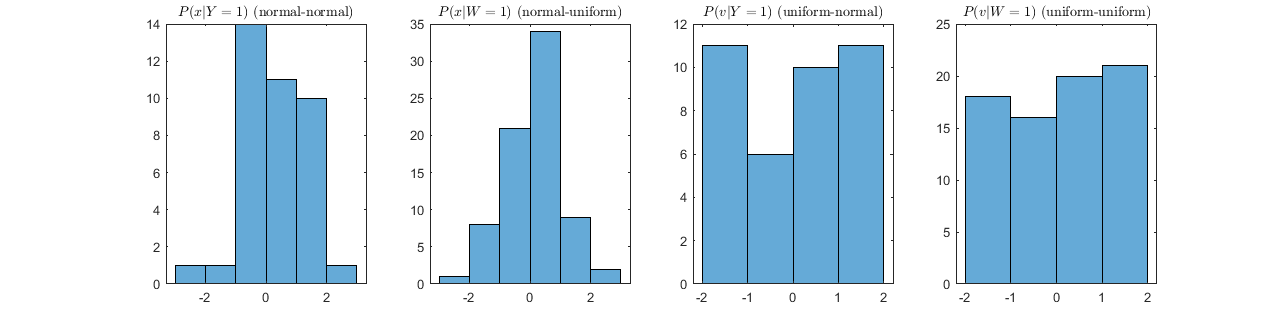

yk = 2;
XcondY = Part1_3(X,Y,yk);
VcondW = Part1_3(V,W,yk);
XcondW = Part1_3(X,W,yk);
VcondY = Part1_3(V,Y,yk);
Fig2 = figure(2);
set(Fig2,'Position',[0 0 2000 500]);
subplot(1,4,1);
histogram(XcondY);
title('$P(x|Y=1)$ (normal-normal)','Interpreter','latex');
subplot(1,4,2);
histogram(XcondW);
title('$P(x|W=1)$ (normal-uniform)','Interpreter','latex');
subplot(1,4,3);
histogram(VcondY);
title('$P(v|Y=1)$ (uniform-normal)','Interpreter','latex');
subplot(1,4,4);
histogram(VcondW);
title('$P(v|W=1)$ (uniform-uniform)','Interpreter','latex');

`Step 4:`

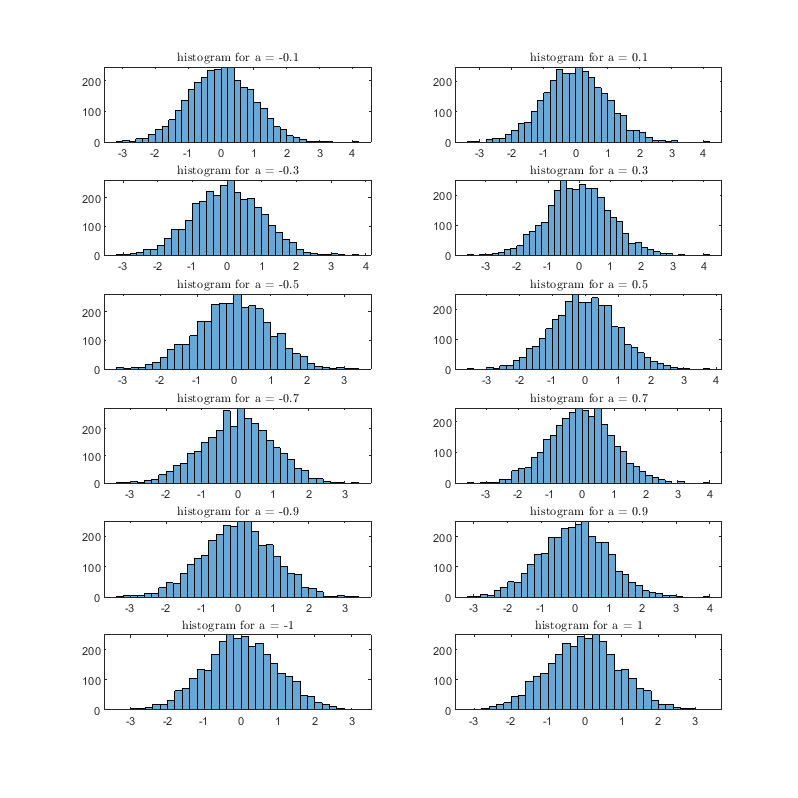

a = [-.1;.1;-.3;.3;-.5;.5;-.7;.7;-.9;.9;-1;1];
Z = a * X + sqrt(1 - a.^2) * Y;
Fig3 = figure(3);
set(Fig3,'Position',[0 0 1000 1000]);
for i = 1:length(a)
    subplot(6,2,i);
    histogram(Z(i,:));
    title(['histogram for a = ',num2str(a(i))],'Interpreter','latex');
end

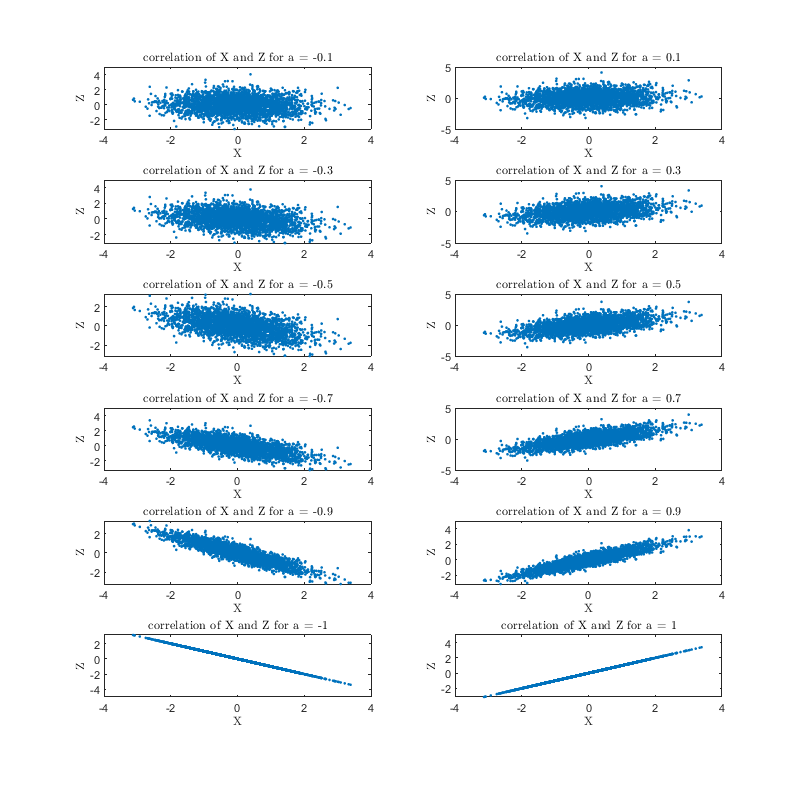

Fig4 = figure(4);
set(Fig4,'Position',[0 0 1000 1000]);
for i = 1:length(a)
    subplot(6,2,i);
    plot(X,Z(i,:),'.');
    title(['correlation of X and Z for a = ',num2str(a(i))],'Interpreter','latex');
    xlabel('X','Interpreter','latex');
    ylabel('Z','Interpreter','latex');
end

# ***Part 2.*** `Random Processes`

`Definition of random processes:`


$$x_1 \left(t\right)=\mathrm{cos}\left(2\pi t+\phi \right)\;\;\;;\;\;\Phi ~U\left\lbrack -\pi ,\pi \right\rbrack$$



$$x_2 \left(t\right)=\cos \left(2\pi t+\phi \right)\;\;\;;\;\;\Phi ~U\left\lbrack -\frac{\pi }{4},\frac{\pi }{4}\right\rbrack$$


clear
fs = 100;
dt = 1/fs;
t = -1:dt:1;

- $x_1 \left(t\right)$ `for 100 random samples:`

Phi1_100 = unifrnd(-pi,pi,[1 100]);
X1_100 = cos(2*pi*ones(length(Phi1_100),1)*t + Phi1_100'*ones(1,length(t)));

- $x_1 \left(t\right)$ `for 1000 random samples:`

Phi1_1000 = unifrnd(-pi,pi,[1 1000]);
X1_1000 = cos(2*pi*ones(length(Phi1_1000),1)*t + Phi1_1000'*ones(1,length(t)));

- $x_1 \left(t\right)$ `for 10000 random samples:`

Phi1_10000 = unifrnd(-pi,pi,[1 10000]);
X1_10000 = cos(2*pi*ones(length(Phi1_10000),1)*t + Phi1_10000'*ones(1,length(t)));

- $x_2 \left(t\right)$ `for 100 random samples:`

Phi2_100 = unifrnd(-pi/4,pi/4,[1 100]);
X2_100 = cos(2*pi*ones(length(Phi2_100),1)*t + Phi2_100'*ones(1,length(t)));

- $x_2 \left(t\right)$ `for 1000 random samples:`

Phi2_1000 = unifrnd(-pi/4,pi/4,[1 1000]);
X2_1000 = cos(2*pi*ones(length(Phi2_1000),1)*t + Phi2_1000'*ones(1,length(t)));

- $x_2 \left(t\right)$ `for 10000 random samples:`

Phi2_10000 = unifrnd(-pi/4,pi/4,[1 10000]);
X2_10000 = cos(2*pi*ones(length(Phi2_10000),1)*t + Phi2_10000'*ones(1,length(t)));

$E\left\lbrack X_1 \left(t\right)\right\rbrack$`:`

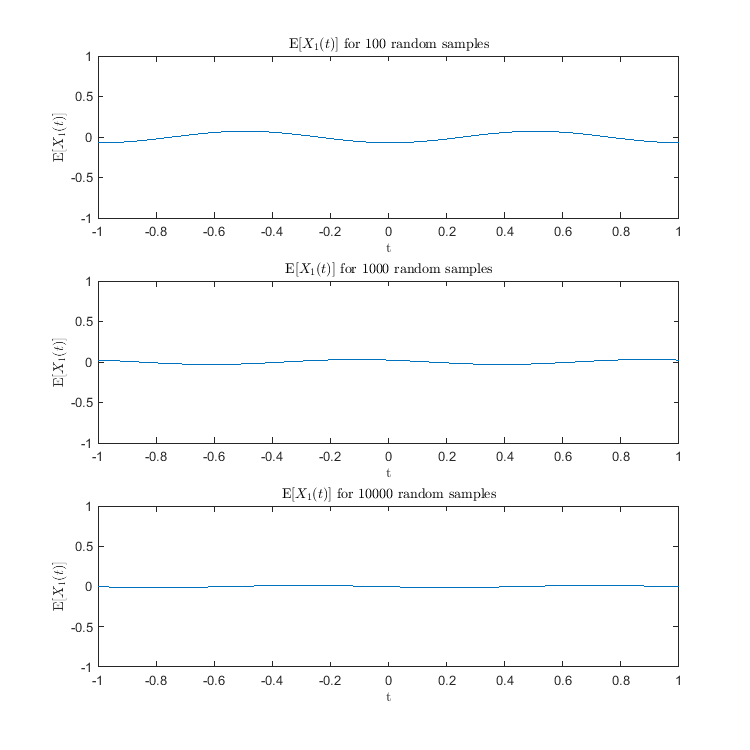

Fig1 = figure(1);
set(Fig1,'Position',[0 0 750 750]);
E_X1_100 = sum(X1_100)/length(Phi1_100);
subplot(3,1,1);
plot(t,E_X1_100);
ylim([-1 1]);
title('E[$X_1(t)$] for 100 random samples','Interpreter','latex');
xlabel('t','Interpreter','latex');
ylabel('E[$X_1(t)$]','Interpreter','latex');
E_X1_1000 = sum(X1_1000)/length(Phi1_1000);
subplot(3,1,2);
plot(t,E_X1_1000);
ylim([-1 1]);
title('E[$X_1(t)$] for 1000 random samples','Interpreter','latex');
xlabel('t','Interpreter','latex');
ylabel('E[$X_1(t)$]','Interpreter','latex');
E_X1_10000 = sum(X1_10000)/length(Phi1_10000);
subplot(3,1,3);
plot(t,E_X1_10000);
ylim([-1 1]);
title('E[$X_1(t)$] for 10000 random samples','Interpreter','latex');
xlabel('t','Interpreter','latex');
ylabel('E[$X_1(t)$]','Interpreter','latex');

$E\left\lbrack X_2 \left(t\right)\right\rbrack$`:`

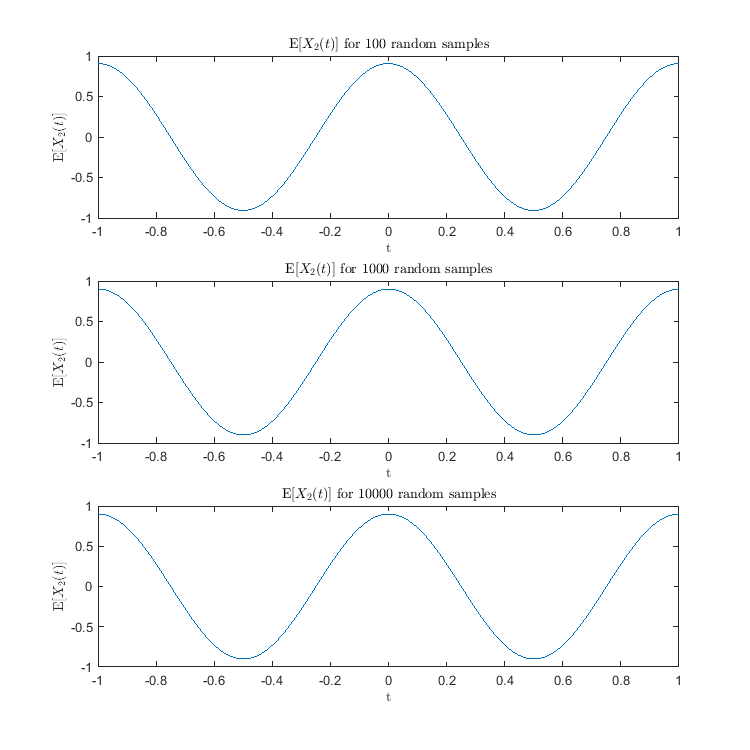

Fig2 = figure(2);
set(Fig2,'Position',[0 0 750 750]);
E_X2_100 = sum(X2_100)/length(Phi2_100);
subplot(3,1,1);
plot(t,E_X2_100);
ylim([-1 1]);
title('E[$X_2(t)$] for 100 random samples','Interpreter','latex');
xlabel('t','Interpreter','latex');
ylabel('E[$X_2(t)$]','Interpreter','latex');
E_X2_1000 = sum(X2_1000)/length(Phi2_1000);
subplot(3,1,2);
plot(t,E_X2_1000);
ylim([-1 1]);
title('E[$X_2(t)$] for 1000 random samples','Interpreter','latex');
xlabel('t','Interpreter','latex');
ylabel('E[$X_2(t)$]','Interpreter','latex');
E_X2_10000 = sum(X2_10000)/length(Phi2_10000);
subplot(3,1,3);
plot(t,E_X2_10000);
ylim([-1 1]);
title('E[$X_2(t)$] for 10000 random samples','Interpreter','latex');
xlabel('t','Interpreter','latex');
ylabel('E[$X_2(t)$]','Interpreter','latex');

`Theorical:`

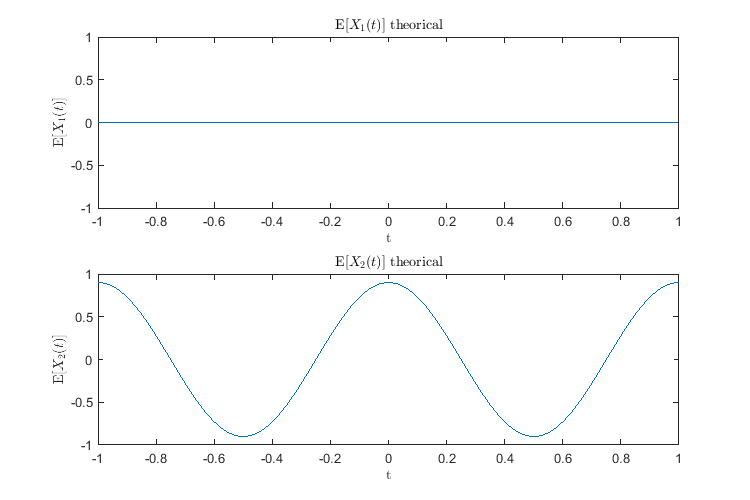

Fig3 = figure(3);
set(Fig3,'Position',[0 0 750 500]);
E_X1 = zeros(1,length(t));
subplot(2,1,1);
plot(t,E_X1);
ylim([-1 1]);
title('E[$X_1(t)$] theorical','Interpreter','latex');
xlabel('t','Interpreter','latex');
ylabel('E[$X_1(t)$]','Interpreter','latex');
E_X2 = 2/pi*(sin(2*pi*t+pi/4) - sin(2*pi*t-pi/4));
subplot(2,1,2);
plot(t,E_X2);
ylim([-1 1]);
title('E[$X_2(t)$] theorical','Interpreter','latex');
xlabel('t','Interpreter','latex');
ylabel('E[$X_2(t)$]','Interpreter','latex');

`Auto correlation: `$R_X \left(t,t+\tau \right)=E\left\lbrack X\left(t\right)X\left(t+\tau \right)\right\rbrack$

tau = -1:dt:1;

$R_{x_1 } \left(t,t+\tau \right)$ `for 100 random samples:`

RX1_100 = zeros(length(t),length(tau));
for i = 1:length(t)
    for j = 1:length(tau)
        RX1_100(i,j) = sum(cos(2*pi*t(i)+Phi1_100).*cos(2*pi*(t(i)+tau(j))+Phi1_100))/length(Phi1_100);
    end
end

$R_{x_1 } \left(t,t+\tau \right)$ `for 1000 random samples:`

RX1_1000 = zeros(length(t),length(tau));
for i = 1:length(t)
    for j = 1:length(tau)
        RX1_1000(i,j) = sum(cos(2*pi*t(i)+Phi1_1000).*cos(2*pi*(t(i)+tau(j))+Phi1_1000))/length(Phi1_1000);
    end
end

`Mesh:`

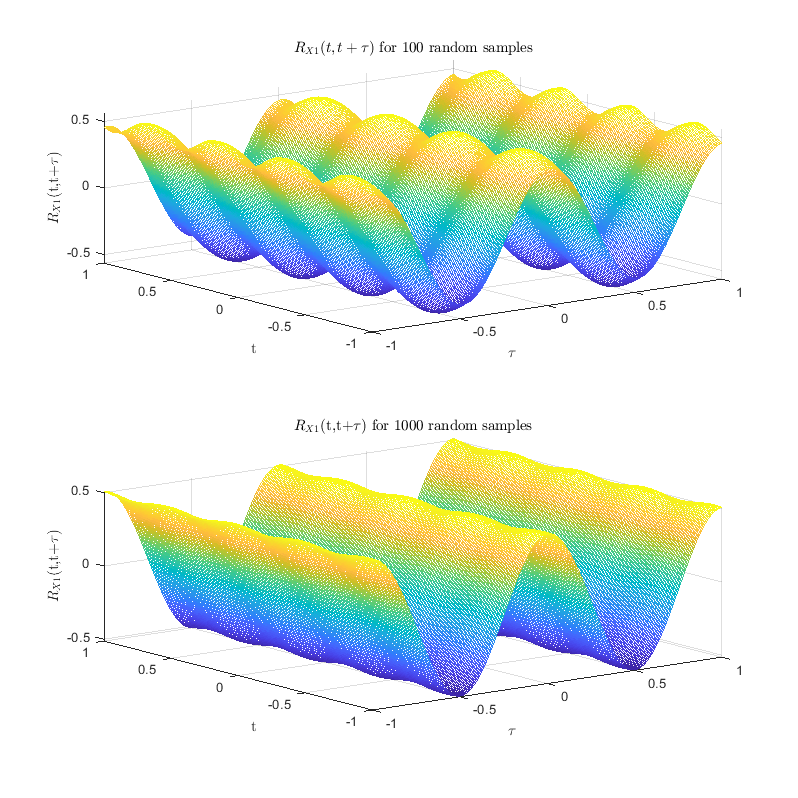

Fig4 = figure(4);
set(Fig4,'Position',[0 0 1000 1000]);
subplot(2,1,1);
mesh(t,tau,RX1_100);
title('$R_{X1}(t,t+\tau)$ for 100 random samples','Interpreter','latex');
xlabel('$\tau$','Interpreter','latex');
ylabel('t','Interpreter','latex');
zlabel('$R_{X1}$(t,t+$\tau$)','Interpreter','latex')
subplot(2,1,2);
mesh(t,tau,RX1_1000);
title('$R_{X1}$(t,t+$\tau$) for 1000 random samples','Interpreter','latex');
xlabel('$\tau$','Interpreter','latex');
ylabel('t','Interpreter','latex');
zlabel('$R_{X1}$(t,t+$\tau$)','Interpreter','latex')

$R_{x_2 } \left(t,t+\tau \right)$ `for 100 random samples:`

RX2_100 = zeros(length(t),length(tau));
for i = 1:length(t)
    for j = 1:length(tau)
        RX2_100(i,j) = sum(cos(2*pi*t(i)+Phi2_100).*cos(2*pi*(t(i)+tau(j))+Phi2_100))/length(Phi2_100);
    end
end

$R_{x_2 } \left(t,t+\tau \right)$ `for 1000 random samples:`

RX2_1000 = zeros(length(t),length(tau));
for i = 1:length(t)
    for j = 1:length(tau)
        RX2_1000(i,j) = sum(cos(2*pi*t(i)+Phi2_1000).*cos(2*pi*(t(i)+tau(j))+Phi2_1000))/length(Phi2_1000);
    end
end

`Mesh:`

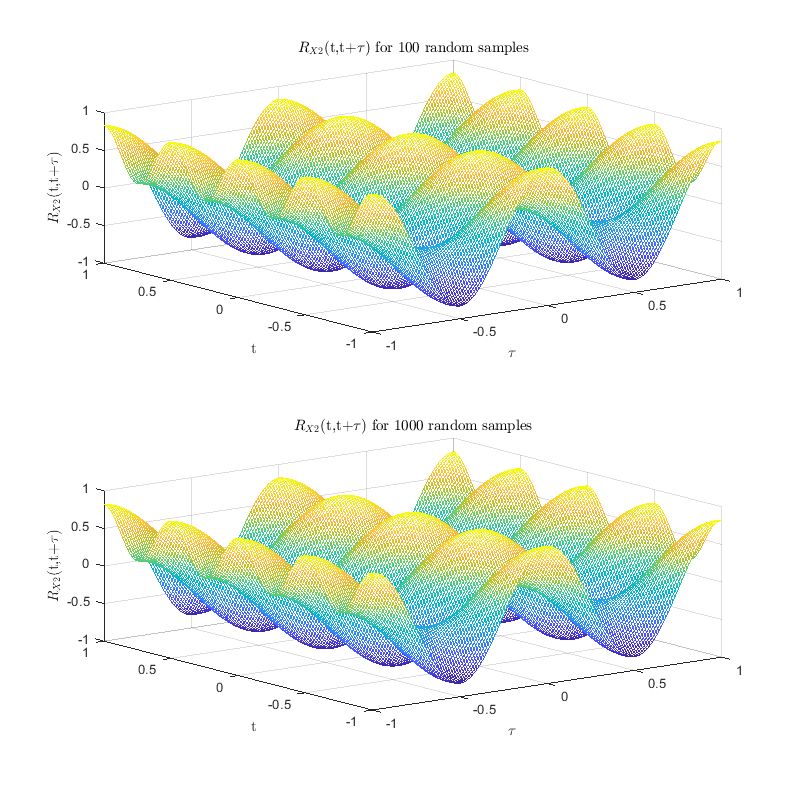

Fig5 = figure(5);
set(Fig5,'Position',[0 0 1000 1000]);
subplot(2,1,1);
mesh(t,tau,RX2_100);
title('$R_{X2}$(t,t+$\tau$) for 100 random samples','Interpreter','latex');
xlabel('$\tau$','Interpreter','latex');
ylabel('t','Interpreter','latex');
zlabel('$R_{X2}$(t,t+$\tau$)','Interpreter','latex')
subplot(2,1,2);
mesh(t,tau,RX2_1000);
title('$R_{X2}$(t,t+$\tau$) for 1000 random samples','Interpreter','latex');
xlabel('$\tau$','Interpreter','latex');
ylabel('t','Interpreter','latex');
zlabel('$R_{X2}$(t,t+$\tau$)','Interpreter','latex')

`Step 5:`


$$R_{\mathrm{X1}} \left(t,t+\tau \right)=\frac{1}{2}\mathrm{cos}\left(2\pi \tau \right)$$



$$R_{\mathrm{X2}} \left(t,t+\tau \right)=\frac{1}{\pi }\cos \left(2\pi \left(2t+\tau \right)\right)+\frac{1}{2}\cos \left(2\pi \tau \right)$$


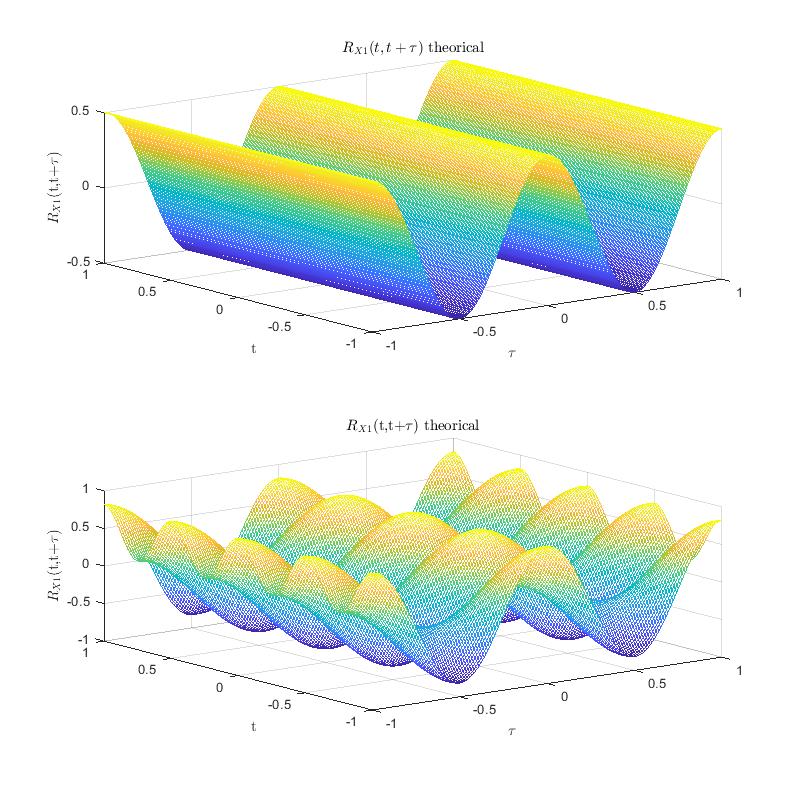

RX1 = 1/2 * ones(length(t),1) * cos(2*pi*tau);
RX2 = 1/pi * cos(2*pi*(2*t'*ones(1,length(tau))+ones(length(t),1)*tau)) +  1/2 * ones(length(t),1) * cos(2*pi*tau);
Fig6 = figure(6);
set(Fig6,'Position',[0 0 1000 1000]);
subplot(2,1,1);
mesh(t,tau,RX1);
title('$R_{X1}(t,t+\tau)$ theorical','Interpreter','latex');
xlabel('$\tau$','Interpreter','latex');
ylabel('t','Interpreter','latex');
zlabel('$R_{X1}$(t,t+$\tau$)','Interpreter','latex')
subplot(2,1,2);
mesh(t,tau,RX2);
title('$R_{X1}$(t,t+$\tau$) theorical','Interpreter','latex');
xlabel('$\tau$','Interpreter','latex');
ylabel('t','Interpreter','latex');
zlabel('$R_{X1}$(t,t+$\tau$)','Interpreter','latex')

RX1_2D_theorical = 1/2 * cos(2*pi*tau);
RX1_2D_100 = sum(RX1_100)/length(t);
RX1_2D_1000 = sum(RX1_1000)/length(t);

`plots:`

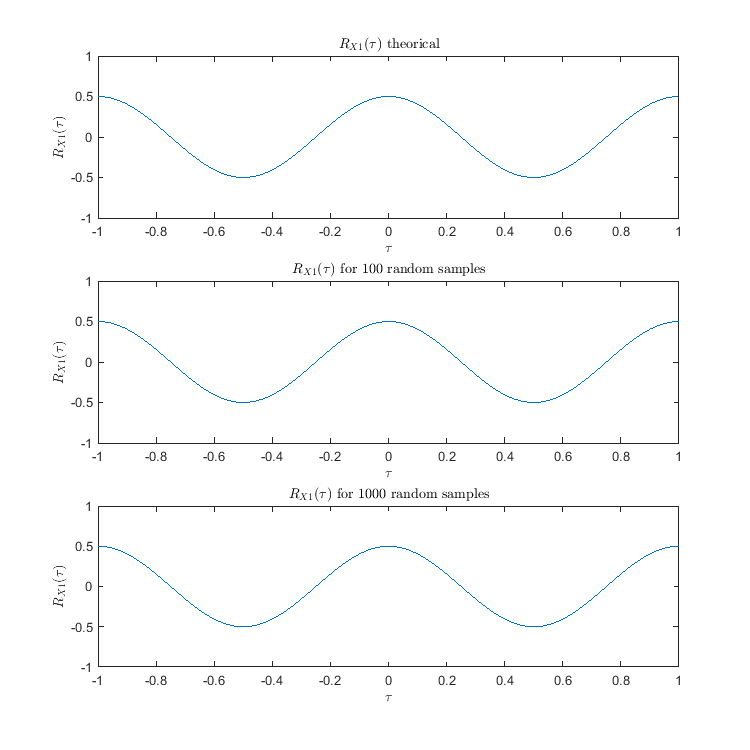

Fig7 = figure(7);
set(Fig7,'Position',[0 0 750 750]);
subplot(3,1,1);
plot(tau,RX1_2D_theorical);
ylim([-1 1]);
title('$R_{X1}(\tau)$ theorical','Interpreter','latex');
xlabel('$\tau$','Interpreter','latex');
ylabel('$R_{X1}(\tau)$','Interpreter','latex');
subplot(3,1,2);
plot(tau,RX1_2D_100);
ylim([-1 1]);
title('$R_{X1}(\tau)$ for 100 random samples','Interpreter','latex');
xlabel('$\tau$','Interpreter','latex');
ylabel('$R_{X1}(\tau)$','Interpreter','latex');
subplot(3,1,3);
plot(tau,RX1_2D_100);
ylim([-1 1]);
title('$R_{X1}(\tau)$ for 1000 random samples','Interpreter','latex');
xlabel('$\tau$','Interpreter','latex');
ylabel('$R_{X1}(\tau)$','Interpreter','latex');

# ***Part 3.*** `Quantization`

`Definition of `$g\left(t\right)=4+\mathrm{sin}\left(2\pi t\right)+\mathrm{cos}\left(\pi t\right)+\mathrm{cos}\left(\frac{\pi t}{2}\right)+\mathrm{tan}\left(\frac{\pi t}{6}\right)$`:`

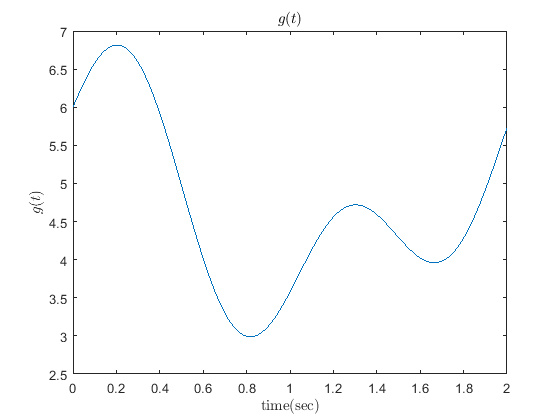

clear
fs_ct = 10000;
dt = 1/fs_ct;
t = 0:dt:2;
g = 4 + sin(2*pi*t) + cos(pi*t) + cos(pi*t/2) + tan(pi*t/6);
figure(1);
plot(t,g);
title('$g(t)$','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$g(t)$','Interpreter','latex');

`Sampling (`$g\left\lbrack n\right\rbrack =g\left(\mathrm{nT}\right)$`):`

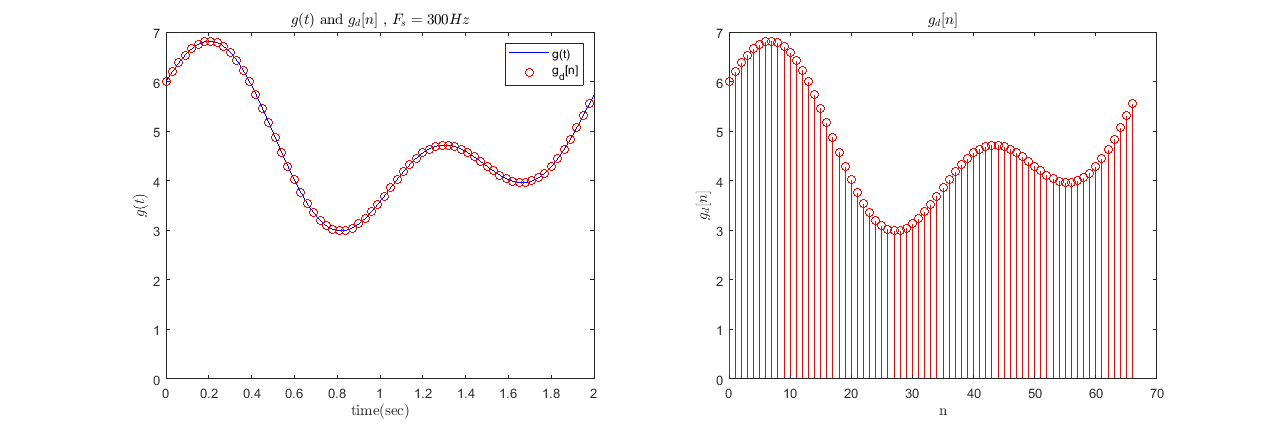

Fs = 300;
Ts = 1/Fs;
gd = g(1:Fs:length(g));
n = 0:length(gd)-1;
Fig2 = figure(2);
set(Fig2,'Position',[0 0 1500 500]);
subplot(1,2,1);
plot(t,g,'b',t(1:Fs:length(g)),gd,'ro');
ylim([0 7]);
title('$g(t)$ and $g_d[n]$ , $F_s=300Hz$','Interpreter','latex');
legend('g(t)','g_d[n]');
xlabel('time(sec)','Interpreter','latex');
ylabel('$g(t)$','Interpreter','latex');
subplot(1,2,2);
stem(n,gd,'r');
title('$g_d[n]$','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('$g_d[n]$','Interpreter','latex');

`Quantization:`

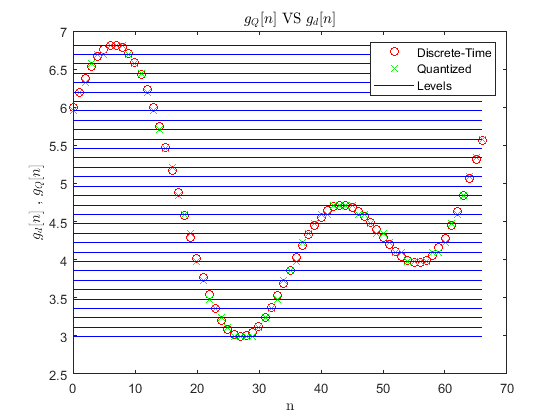

q = 32;
qlevels = linspace(min(gd),max(gd),q);
g_quantized = qlevels(end)*ones(1,length(n));
for i = 1:length(n)
    for m = 1:q-1
        dq = qlevels(m+1)-qlevels(m);
        if(gd(i)>=qlevels(m) && gd(i)<qlevels(m+1))
            near = floor(2 * (gd(i)-qlevels(m))/dq);
            g_quantized(i) = qlevels(m) + near*(qlevels(m+1)-qlevels(m));
        end
    end
end
Fig3 = figure(3);
lines = qlevels' * ones(1,length(n));
plot(n,gd,'ro',n,g_quantized,'gx',n,lines,'b');
ylim([2.5 7]);
legend('Discrete-Time','Quantized','Levels');
title('$g_Q[n]$ VS $g_d[n]$','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('$g_d[n]$ , $g_Q[n]$','Interpreter','latex');

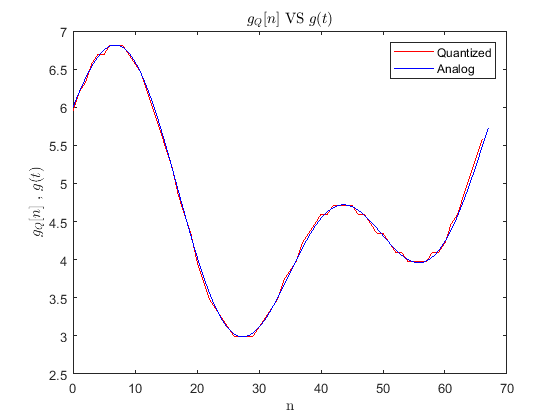

Fig4 = figure(4);
plot(n,g_quantized,'r',t/2*length(n),g,'b');
ylim([2.5 7]);
legend('Quantized','Analog');
title('$g_Q[n]$ VS $g(t)$','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('$g_Q[n]$ , $g(t)$','Interpreter','latex');

`Discrete-Time Signal Energy:` 

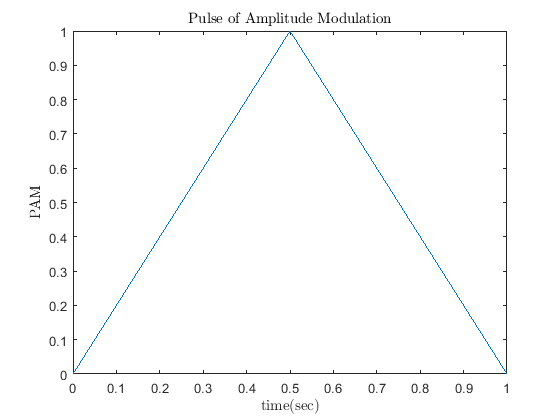

Fs_pulse = 1000;
dt_pulse = 1/Fs_pulse;
t_pulse = dt_pulse:dt_pulse:1;
PAM = importdata('p.mat');
plot(t_pulse,PAM);
title('Pulse of Amplitude Modulation','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('PAM','Interpreter','latex');

PAM_Energy = sum(PAM.^2);
fprintf('Enery of DT-PAM = %.3f',PAM_Energy);

Enery of DT-PAM = 333.334

`Pulse Code Modulation:`

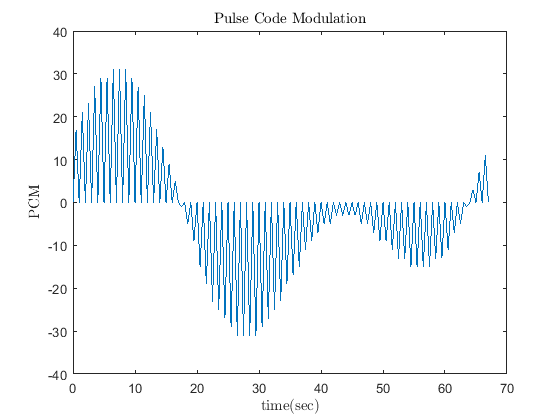

L = length(PAM);
digit = 0:q-1;
amp = -31:2:31;
graycode = dec2bin(bin2gray(digit','pam',32),5);
levels_digit_grey = [qlevels;digit;amp];
PCM = []; t_PCM = []; PCM_gray = [];
for i = 1:length(g_quantized)
    j = find(levels_digit_grey(1,:) == g_quantized(i));
    PCM((i-1)*L+1:i*L) = PAM*levels_digit_grey(3,j);
    t_PCM((i-1)*L+1:i*L) = (i-1)+t_pulse;
    PCM_gray = [PCM_gray ; graycode(j,:)];
end
plot(t_PCM,PCM);
title('Pulse Code Modulation','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('PCM','Interpreter','latex');

for i = 1:length(n)
    fprintf('%s ',PCM_gray(i,1:5));
end

10100 10111 10110 10011 10001 10001 10000 10000 10000 10001 10011 10010 10111 10100 11101 11110 11011 01000 01011 01110 01100 00101 00110 00010 00011 00001 00000 00000 00000 00000 00001 00011 00010 00110 00101 00100 01100 01111 01110 01010 01011 01011 01001 01001 01001 01001 01011 01011 01010 01110 01110 01111 01101 01101 01100 01100 01100 01100 01101 01101 01111 01010 01011 01000 11001 11010 11111 

`Step 5:`


$${\left(\frac{S}{N}\right)}_R =\mathrm{SNR}\to N_R =\mathrm{SNR}\ldotp S_R \;\;\;,\;S_R =\frac{\sigma_S^2 }{N\left(\mathrm{number}\;\mathrm{of}\;\mathrm{samples}\right)}$$


num = length(PCM);
S = sum(PCM.^2)/num;
SNRdB = 20;
SNR = 10^(SNRdB/10);
N = S/SNR;
var = N;
fprintf('Variance = %.3f',var);

Variance = 1.158

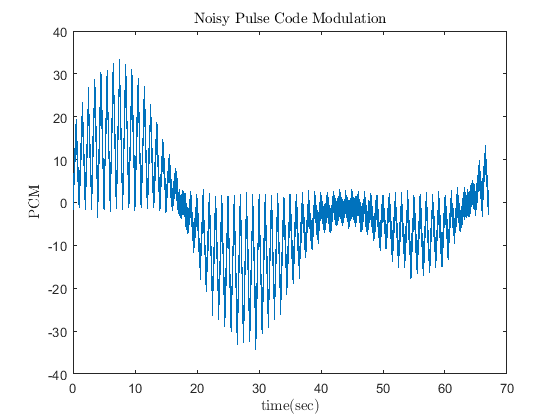

mu = 0;
noise = normrnd(mu,sqrt(var),[1 length(PCM)]);
noisyPCM = noise + PCM;
plot(t_PCM,noisyPCM);
title('Noisy Pulse Code Modulation','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('PCM','Interpreter','latex');

`Decoding:`

mutEnergy = zeros(1,length(noisyPCM)*dt_pulse);
for i = 1:length(mutEnergy)
   mutEnergy(i) = sum(PAM.*noisyPCM((i-1)*L+1:i*L));
end
Domain = mutEnergy/PAM_Energy;

`find level of quantization: (Reconstruction of Quantized Signal)`

NormalDomain = zeros(1,length(Domain));
RecQuantized = zeros(1,length(Domain));
for i = 1:length(Domain)
    for m = 1:q-1
        dA = levels_digit_grey(3,m+1)-levels_digit_grey(3,m);
        if(Domain(i)>=levels_digit_grey(3,m) && Domain(i)<=levels_digit_grey(3,m+1))
            near = floor(2 * (Domain(i)-levels_digit_grey(3,m))/dA);
            NormalDomain(i) = levels_digit_grey(3,m) + near*(levels_digit_grey(3,m+1)-levels_digit_grey(3,m));
        elseif(Domain(i)>levels_digit_grey(3,end))
            NormalDomain(i) = levels_digit_grey(3,end);
        elseif(Domain(i)<levels_digit_grey(3,1))
            NormalDomain(i) = levels_digit_grey(3,1);
        end
    end
    j = find(levels_digit_grey(3,:) == NormalDomain(i));
    RecQuantized(i) = levels_digit_grey(1,j);
end

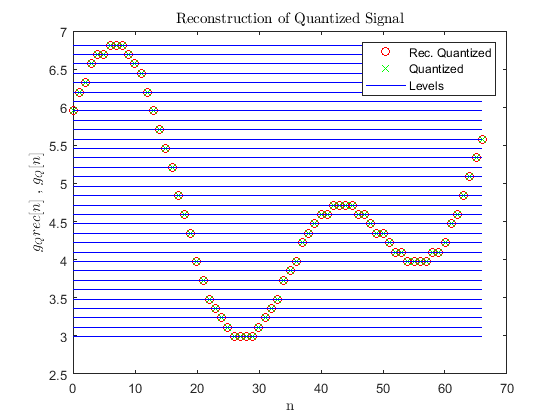

plot(n,RecQuantized,'ro',n,g_quantized,'gx',n,lines,'b');
ylim([2.5 7]);
legend('Rec. Quantized','Quantized','Levels');
title('Reconstruction of Quantized Signal','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('$g_Qrec[n]$ , $g_Q[n]$','Interpreter','latex');

isequal(RecQuantized,g_quantized)

ans = logical
   1


`Quantization on down level:`

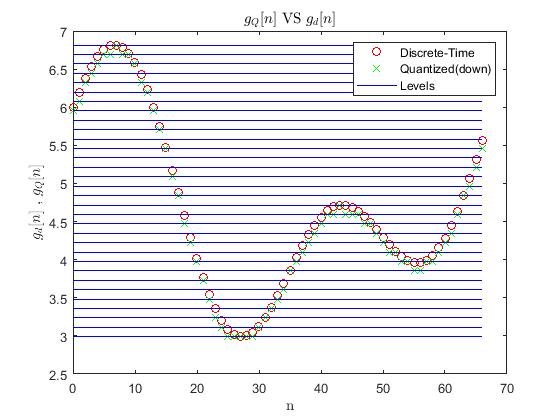

Q_down = qlevels(end)*ones(1,length(n));
for i = 1:length(n)
    for m = 1:q-1
        dq = qlevels(m+1)-qlevels(m);
        if(gd(i)>=qlevels(m) && gd(i)<qlevels(m+1))
            Q_down(i) = qlevels(m);
        end
    end
end
plot(n,gd,'ro',n,Q_down,'gx',n,lines,'b');
ylim([2.5 7]);
legend('Discrete-Time','Quantized(down)','Levels');
title('$g_Q[n]$ VS $g_d[n]$','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('$g_d[n]$ , $g_Q[n]$','Interpreter','latex');

`Quantization on down level:`

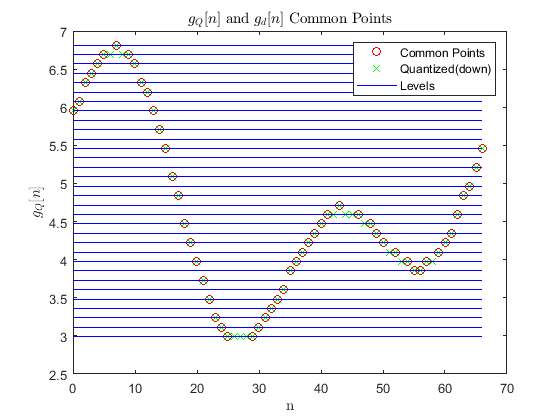

ComPoints = Q_down(1);
n_ComPoints = n(1);
for i = 2:length(n)-1
    if(Q_down(i-1)<Q_down(i) && Q_down(i)<=Q_down(i+1))
        ComPoints = [ComPoints Q_down(i)]; %Ascending and Maximum
        n_ComPoints = [n_ComPoints n(i)];
    elseif(Q_down(i-1)>=Q_down(i) && Q_down(i)>Q_down(i+1))
        ComPoints = [ComPoints Q_down(i)]; %Descending and Maximum
        n_ComPoints = [n_ComPoints n(i)];
    elseif(Q_down(i-1)<Q_down(i) && Q_down(i)>Q_down(i+1))
        ComPoints = [ComPoints Q_down(i)]; %One point Maximum
        n_ComPoints = [n_ComPoints n(i)];
    else %Minimum
        for j = i+1:length(n)-1
            if(Q_down(i)~=Q_down(j))
                afLast = Q_down(j);
                break
            end
        end
        for j = i-1:-1:1
            if(Q_down(i)~=Q_down(j))
                befFirst = Q_down(j);
                break
            end            
        end
        if(Q_down(i-1)>Q_down(i) && Q_down(i)<=Q_down(i+1) && Q_down(i)<afLast && Q_down(i)<befFirst)
            ComPoints = [ComPoints Q_down(i)]; 
            n_ComPoints = [n_ComPoints n(i)];
        elseif(Q_down(i-1)==Q_down(i) && Q_down(i)<Q_down(i+1) && Q_down(i)<afLast && Q_down(i)<befFirst)
            ComPoints = [ComPoints Q_down(i)]; 
            n_ComPoints = [n_ComPoints n(i)];
        end
    end
end
ComPoints = [ComPoints Q_down(end)];
n_ComPoints = [n_ComPoints n(end)];
plot(n_ComPoints,ComPoints,'ro',n,Q_down,'gx',n,lines,'b');
ylim([2.5 7]);
legend('Common Points','Quantized(down)','Levels');
title('$g_Q[n]$ and $g_d[n]$ Common Points','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('$g_Q[n]$','Interpreter','latex');

`Spline:`

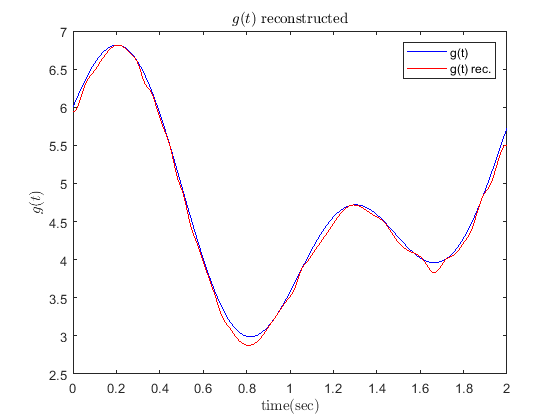

g_rec = spline(n_ComPoints*Fs/fs_ct,ComPoints,t);
plot(t,g,'b',t,g_rec,'r');
legend('g(t)','g(t) rec.');
title('$g(t)$ reconstructed','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$g(t)$','Interpreter','latex');

immse(g,g_rec)

ans = 0.0046

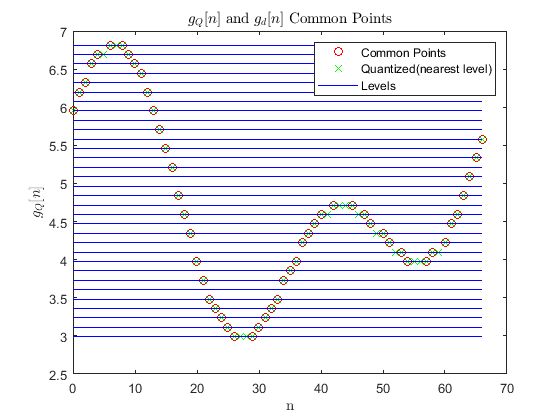

g_quantized;
ComPoints2 = g_quantized(1);
n_ComPoints2 = n(1);
for i = 2:length(n)-1
    if(g_quantized(i-1)<g_quantized(i) && g_quantized(i)<=g_quantized(i+1))
        ComPoints2 = [ComPoints2 g_quantized(i)]; %Ascending and Maximum
        n_ComPoints2 = [n_ComPoints2 n(i)];
    elseif(g_quantized(i-1)>=g_quantized(i) && g_quantized(i)>g_quantized(i+1))
        ComPoints2 = [ComPoints2 g_quantized(i)]; %Descending and Maximum
        n_ComPoints2 = [n_ComPoints2 n(i)];
    elseif(g_quantized(i-1)<g_quantized(i) && g_quantized(i)>g_quantized(i+1))
        ComPoints2 = [ComPoints2 Q_down(i)]; %One point Maximum
        n_ComPoints2 = [n_ComPoints2 n(i)];
    else %Minimum
        for j = i+1:length(n)-1
            if(g_quantized(i)~=g_quantized(j))
                afLast = g_quantized(j);
                break
            end
        end
        for j = i-1:-1:1
            if(g_quantized(i)~=g_quantized(j))
                befFirst = g_quantized(j);
                break
            end            
        end
        if(g_quantized(i-1)>g_quantized(i) && g_quantized(i)<=g_quantized(i+1) && g_quantized(i)<afLast && g_quantized(i)<befFirst)
            ComPoints2 = [ComPoints2 g_quantized(i)]; 
            n_ComPoints2 = [n_ComPoints2 n(i)];
        elseif(g_quantized(i-1)==g_quantized(i) && g_quantized(i)<g_quantized(i+1) && g_quantized(i)<afLast && g_quantized(i)<befFirst)
            ComPoints2 = [ComPoints2 g_quantized(i)]; 
            n_ComPoints2 = [n_ComPoints2 n(i)];
        end
    end
end
ComPoints2 = [ComPoints2 g_quantized(end)];
n_ComPoints2 = [n_ComPoints2 n(end)];
plot(n_ComPoints2,ComPoints2,'ro',n,g_quantized,'gx',n,lines,'b');
ylim([2.5 7]);
legend('Common Points','Quantized(nearest level)','Levels');
title('$g_Q[n]$ and $g_d[n]$ Common Points','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('$g_Q[n]$','Interpreter','latex');

`Spline:`

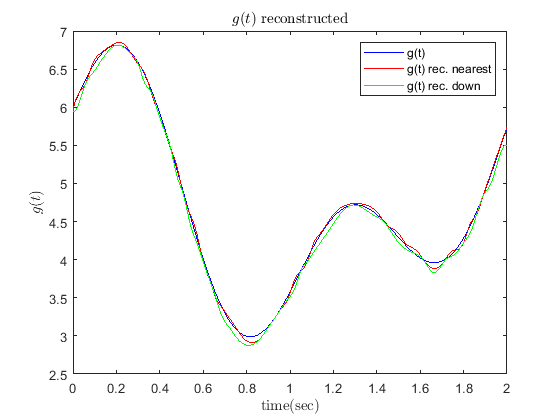

g_rec2 = spline(n_ComPoints2*Fs/fs_ct,ComPoints2,t);
plot(t,g,'b',t,g_rec2,'r',t,g_rec,'g');
legend('g(t)','g(t) rec. nearest','g(t) rec. down');
title('$g(t)$ reconstructed','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$g(t)$','Interpreter','latex');

immse(g,g_rec2)

ans = 0.0012

# `Functions:`

`Part 1. ``Problem 1 `

function Part1_1(X,Y,muX,muY)
    Sigma = corrcoef(X,Y);
    Mu = [muX muY];
    sortX = sort(X);
    sortY = sort(Y);
    [mX,mY] = meshgrid(sortX,sortY);
    Z = mvnpdf([mX(:) mY(:)],Mu,Sigma);
    JointXY = reshape(Z,length(mX),length(mY));
    contour(mX,mY,JointXY);
end

`Part 1.`` Problem 2`

function [XcondY] = Part1_3(X,Y,yk)
    XcondY = [];
    delta = 0.1;
    for i = 1:length(X)
        if((Y(i)-delta)<yk && yk<(Y(i)+delta))
            XcondY = [XcondY X(i)]; 
        end
    end
end
    